# **Redshift study**

close all
clear variables

## Data import

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

## Constants

lambdaPr = 656.28; %nm
speedOfLight = 299792.458; %kph
mW = {};

## Determine range of wavelengths

nObs = size(spectra, 1);
nStars = size(spectra, 2);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

## Calculate distancing speed 

speed = (zeros(1, nStars))';
for i = 1:nStars
    intensivity = spectra(:, i);
    [sHa, idx] = min(intensivity);
    z = (lambda(idx)/lambdaPr) - 1;
    speed(i) = z * speedOfLight;
end

## Movaway stars

for i = 1:nStars
    if speed(i) > 0
        mW(end+1) = starNames(i);
    end
end
movaway = (mW)';

## Plotting

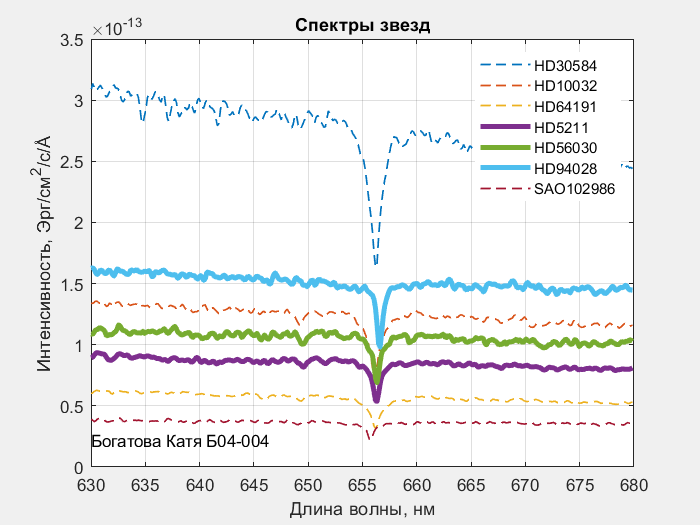

fg1 = figure;
set(gcf, 'Visible', 'on');
for i = 1:nStars
    if speed(i) < 0
        plot(lambda, spectra(:, i), '--', 'LineWidth', 1);
    else
        plot(lambda, spectra(:, i), 'LineWidth', 3);
    end
    hold on
end
legend(starNames, 'Location', 'northeast');
text(lambdaStart, min(intensivity), 'Дарья Грязнова Б04-004');
xlabel('Длина волны, нм');
ylabel(['Интенсивность, Эрг/см^2/c/', char(197)]);
title('Спектры звезд');
grid on
hold off

## Save plot

saveas(fg1, 'Спектры.png')